% sanity_check.m


# Sanity check

clear;
clc;

# Build rhythmic mRNA degradation model and construct parameter distribution

Rhythmic_mRNA_model = bbModel(@Sarah_Rhythmic_mRNA,5,3,'OutputType',[0 0 0]);

p = 4; % group number
q = 10; % group size
d = 5; % number of parameters 
index = 2; % the ith parameter 

% create parameter distribution
size = 10000;

amp_pd = makedist('Uniform','lower',0,'upper',1);
phase_pd = makedist('Uniform','lower',0,'upper',24);

Kd_pd_log= makedist('Uniform','lower',-1.58,'upper',1.415);
Kd_pd = 10.^random(Kd_pd_log,[size,1]);

params = {amp_pd phase_pd Kd_pd amp_pd phase_pd};


# Histogram of parameter Kd

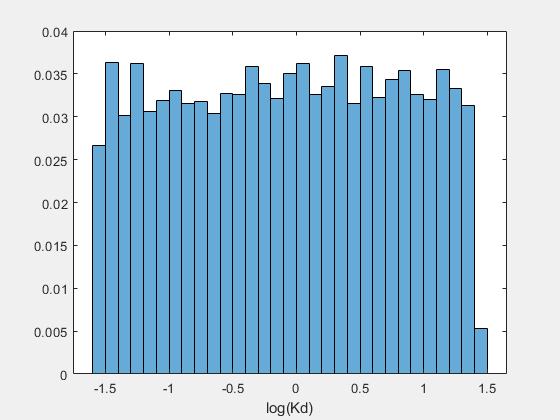

f = figure;
set(f, 'Visible', 'on');
histogram(log10(Kd_pd),'Normalization','probability')
xlabel('log(Kd)')

# Parameter sampling

### Unit cube

Single unit cube correspopnds to the parameter samples for single Sobol indices calculation, where the ith parameter values are fixed within each group and other parameter values unfixed. All parameter values are varied across groups (indicated by different colors). 

[SingleCube,TotalCube] = generate_Nested_cube(p,q,d,index);

figure;
for j=1:p
   subplot(2,2,1)
   plot(1:q,SingleCube(j,:,index)','-x');
   hold on; 
   xlim([0 q+1]);
   ylim([0 1])
   title('Single Unit cube ith')
end 
hold off;


for j=1:p
   subplot(2,2,2)
   plot(1:q,TotalCube(j,:,index)','-x');
   hold on; 
   xlim([0 q+1]);
   ylim([0 1])
   title('Total Unit cube ith')
end   
hold off;

for j=1:p
   subplot(2,2,3)
   plot(1:q,SingleCube(j,:,index+1)','-x');
   hold on; 
   xlim([0 q+1]);
   ylim([0 1])
   title('Single Unit cube i+1 parameter')
end    
hold off;

for j=1:p
   subplot(2,2,4)
   plot(1:q,TotalCube(j,:,index+1)','-x');
   hold on; 
   xlim([0 q+1]);
   ylim([0 1])
   title('Total Unit cube i+1 parameter')
end   
hold off

# Parameter space

[SinglePar,TotalPar] = generate_Nested_Parameter(params,p,q,d,index);

figure;
for j=1:p
   subplot(2,2,1)
   plot(1:q,SinglePar(j,:,index)','-x');
   hold on; 
   xlim([0 q+1]);  
   title('Single ith parameter')
  
end      
hold off;   

for j=1:p   
   subplot(2,2,2)
   plot(1:q,TotalPar(j,:,index)','-x');
   hold on; 
   xlim([0 q+1]);
   title('Total ith parameter')  
end   
hold off;


for j=1:p   
   subplot(2,2,3)
   plot(1:q,SinglePar(j,:,index+1)','-x');
   hold on; 
   xlim([0 q+1]);
   title('Total i+1 th parameter')  
end   
hold off;
for j=1:p   
   subplot(2,2,4)
   plot(1:q,TotalPar(j,:,index+1)','-x');
   hold on; 
   xlim([0 q+1]);
   title('Total i+1 th parameter')  
end   
hold off;

# Parameter from AB Sampling

N = 10;
d = 5;
[par_A,par_B,par_AB] = generate_AB_Parameter(N,d,params)

par_A =     0.9648   19.9185   11.9105    0.9556    8.1984
    0.0488   18.9081   15.0416    0.4754    2.9506
    0.4209   11.2921    4.1515    0.7117    5.4234
    0.7278    0.9171   13.9911    0.5704   15.7131
    0.5489    7.3772    2.5373    0.0669    1.9114
    0.1463   14.4858    0.0581    0.8613   13.7413
    0.2394    5.8246    0.6216    0.6499   21.9831
    0.6029   22.0420    0.0698    0.1529   17.3516
    0.3409    4.7290    2.8489    0.3663   10.1273
    0.8379   14.2493    2.4258    0.2713   20.6130


par_B =     0.6898   11.1619    0.6657    0.9264   14.4281
    0.8558    4.0143    1.0596    0.5720    3.6705
    0.0476   17.2808    7.4548    0.6079   23.1888
    0.1327   23.7924    0.6003    0.0026   18.8909
    0.2213   14.0540    0.0385    0.2838   13.3218
    0.5753    1.5337   24.0903    0.4617    9.0003
    0.4917   14.9684    0.0484    0.7740   11.6742
    0.7764    6.5254    0.1149    0.1475   19.4818
    0.9220   19.9597    0.4765    0.3074    4.9182
    0.3914    8.6178    0.1072    0.8332    0.3951


par_AB =     0.6898   19.9185   11.9105    0.9556    8.1984
    0.8558   18.9081   15.0416    0.4754    2.9506
    0.0476   11.2921    4.1515    0.7117    5.4234
    0.1327    0.9171   13.9911    0.5704   15.7131
    0.2213    7.3772    2.5373    0.0669    1.9114
    0.5753   14.4858    0.0581    0.8613   13.7413
    0.4917    5.8246    0.6216    0.6499   21.9831
    0.7764   22.0420    0.0698    0.1529   17.3516
    0.9220    4.7290    2.8489    0.3663   10.1273
    0.3914   14.2493    2.4258    0.2713   20.6130



figure;
subplot(1,3,1)
for i=1:d
    plot(ones(N,1)*i,par_A(:,i),'-x');
    hold on;
end
hold off;

% subplot(1,3,2)
% for i=1:d
%     plot(ones(N,1)*i,par_B(:,i),'-^');
% end
% 
% subplot(1,3,3)
% for i=1:d
%     
%     
% end

# Comparision between AB Sampling and Nested Sampling with group size = 2

### **Non-circular AB Sampling**

tStart = tic;
% hyper parameter for batch run
batch_size = 10;


% batch run
input_number = Rhythmic_mRNA_model.ParNumber;
output_number = Rhythmic_mRNA_model.OutputNumber;

S1_batch = zeros(batch_size,output_number,input_number);
ST_batch = zeros(batch_size,output_number,input_number);

f = waitbar(0,'Start batch running ...');

for i=1:batch_size
    % update waitbar
    waitbar(i/batch_size, f, sprintf('Progress: %d %%', floor(i/batch_size*100)));
   
    
    [S1, ST] = CircularSobol(Rhythmic_mRNA_model, params,'method','nonCircular','SampleSize',10^3,'formula',1,...
                                                            'GroupNumber',1000,'GroupSize',2,'plot',0,'progress',0);
    S1_batch(i,:,:) = S1;
    ST_batch(i,:,:) = ST;
    
    fprintf('Finished running the batch %d \n',i);
end

Starting parallel pool (parpool) using the 'local' profile ...




close(f); % close wait bar

% calculate mean and std 
mean_S1 = mean(S1_batch);
std_S1 = std(S1_batch);

mean_ST = mean(ST_batch);
std_ST = std(ST_batch);

%plot_matrix = [S1_plot;ST_plot]';
mean_matrix = [mean_S1;mean_ST];
error_matrix = [std_S1;std_ST];

for i=1:output_number
    
    figure;
    tmp_mean = reshape(mean_matrix(:,i,:),[2,input_number])';
    b = bar(tmp_mean,'grouped');

    % plot error bar
    tmp_error = reshape(error_matrix(:,i,:),[2,input_number])';

    hold on;
    % Find the number of groups and the number of bars in each group
    [ngroups,nbars] = size(tmp_mean);
    
    % for R2019a and earlier

    % Calculate the width for each bar group
    groupwidth = min(0.8, nbars/(nbars + 1.5));
    
    % Set the position of each error bar in the centre of the main bar
    for j = 1:nbars
        % Calculate center of each bar
        x = (1:ngroups) - groupwidth/2 + (2*j-1) * groupwidth / (2*nbars);
        errorbar(x, tmp_mean(:,j), tmp_error(:,j), 'k', 'linestyle', 'none');
    end
    
%     % for R2019b and later
%     % Calculate the width for each bar group
%     x_cor = nan(nbars, ngroups);
%     for j = 1:nbars
%         x_cor(j,:) = b(j).XEndPoints;
%     end 
%     % Plot the errorbars
%     errorbar(x_cor',tmp_mean,tmp_error,'k','linestyle','none');
    
    hold off

    ylim([0 1])
    legend('Single','Total')
    legend boxoff
    yticks(0:.5:1)
    set(gca,'FontSize',20)
    set(gca,'LineWidth',2)
end

tEnd = toc(tStart);
fprintf('The running took %s \n', duration([0, 0, tEnd]));